#                          Approximating Fitness (Deformation Energy) By A Neural Network

## Clearing workspace

clc;
clear;
close all;

## Reading Dataset

filename='Dataset.csv';
data=csvread(filename);
x=data(:,1:13)';    %13 decision variables
y=data(:,14)';      % Dependent variable

## Building Model Architecture

trainFct='trainbr';
hidden_neurons_layer1=20;
hidden_neurons_layer2=20;
hidden_neurons_layer3=20;
hidden_neurons_layer4=20;
hidden_neurons_layer5=20;

architecture=[hidden_neurons_layer1 hidden_neurons_layer2 hidden_neurons_layer3 hidden_neurons_layer4 hidden_neurons_layer5];

## Fitting the model

net=fitnet(architecture,trainFct);
net.layers{2}.transferFcn='tansig';
net.layers{3}.transferFcn='tansig';
net.layers{4}.transferFcn='tansig';
net.layers{5}.transferFcn='tansig';
net.layers{6}.transferFcn='tansig';
net.layers{net.numLayers}.transferFcn = 'purelin';

## Parametrisation of the model

net.divideFcn='dividerand';
net.divideMode='sample';
net.divideParam.trainRatio=0.8;
net.divideParam.valRatio=0.1;
net.divideParam.testRatio=0.1;
net.trainParam.epochs=1000;
net.performFcn='mse';

## Training of the model

[net,tr]=train(net,x,y);

## Saving the model

save ./model/net;

## Loading the model

model = load('./model/net.mat')

## View the neural network architecture

view(model.net.net)

## Evaluating neural network performance

tr = model.net.tr

tr = struct with fields:
        trainFcn: 'trainbr'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×90000 double]
          valInd: []
         testInd: [1×10000 double]
            stop: 'User stop.'
      num_epochs: 211
       trainMask: {[1×100000 double]}
         valMask: {[1×100000 double]}
        testMask: {[1×100000 double]}
      best_epoch: 211
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradient'  'gamk'  'ssX'  'val_fail'}
           epoch: [1×212 double]
            time: [1×212 double]
            perf: [1×212 double]
           vperf: [1×212 double]
           tperf: [1×212 double]
              mu: [1×212 double]
        gradient: [1×212 double]
            gamk: [1×212 double]
             ssX: [1×212 double]
        val_fail: [1×212 double]
  

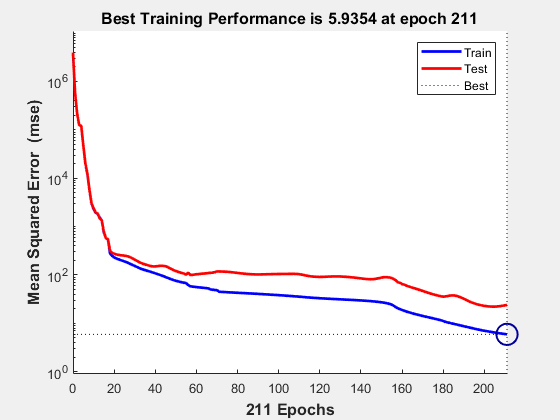

plotperform(tr)